%initialize collection variables

%


        o = 1;
        combined_tau = zeros(10,100);
        
        p = 1;
        combined_tau_means = zeros(100,1);
        
        peaks = zeros(10,1);
        
        
        
        binned_Tau = NaN(10,200);
                  
                    aa = 1;
                    bb = 1;
                    cc = 1;
                    dd = 1;
                    ee = 1;
                    ff = 1;
                    gg = 1;
                    hh = 1;
                    jj = 1;
                    kk = 1;
                    
        combined_binned_Tau = NaN(10,200);
        
                    x = 1;
                   
                    aaa = 1;
                    bbb = 1;
                    ccc = 1;
                    ddd = 1;
                    eee = 1;
                    fff = 1;
                    ggg = 1;
                    hhh = 1;
                    jjj = 1;
                    kkk = 1;
                    
        rep_traces = NaN(100, 40000);
        
       % aaa = 1;
       
%




t = c001_Time*1000;
in = [c002_Current_1; c003_Current_1; c004_Current_1; c005_Current_1; c006_Current_1; c007_Current_1; c008_Current_1; c009_Current_1; c010_Current_1; c011_Current_1]*1000000000;
%in = [c002_Current_1; c003_Current_1; c004_Current_1; c005_Current_1; c006_Current_1; c007_Current_1; c008_Current_1; c009_Current_1; c011_Current_1; c012_Current_1]*1000000000;

clear c002_Current_1 c003_Current_1 c004_Current_1 c005_Current_1 c006_Current_1 c007_Current_1 c008_Current_1 c009_Current_1 c010_Current_1 c011_Current_1


t_zero = t-500;


% baseline sweeps 

for k = 1:10
    baseline(k) = mean(in(k,9960:10040));
end

clear k

a = baseline';

in = in - a;


Tau = zeros(10,1);






for i = 1:10;
    in_peaks(i) = max(in(i,10040:14000));
end


in_peaks'

ans =     0.6419
    1.2763
    1.7644
    2.0739
    2.9636
    2.9214
    2.9265
    2.7925
    2.9730
    3.2321


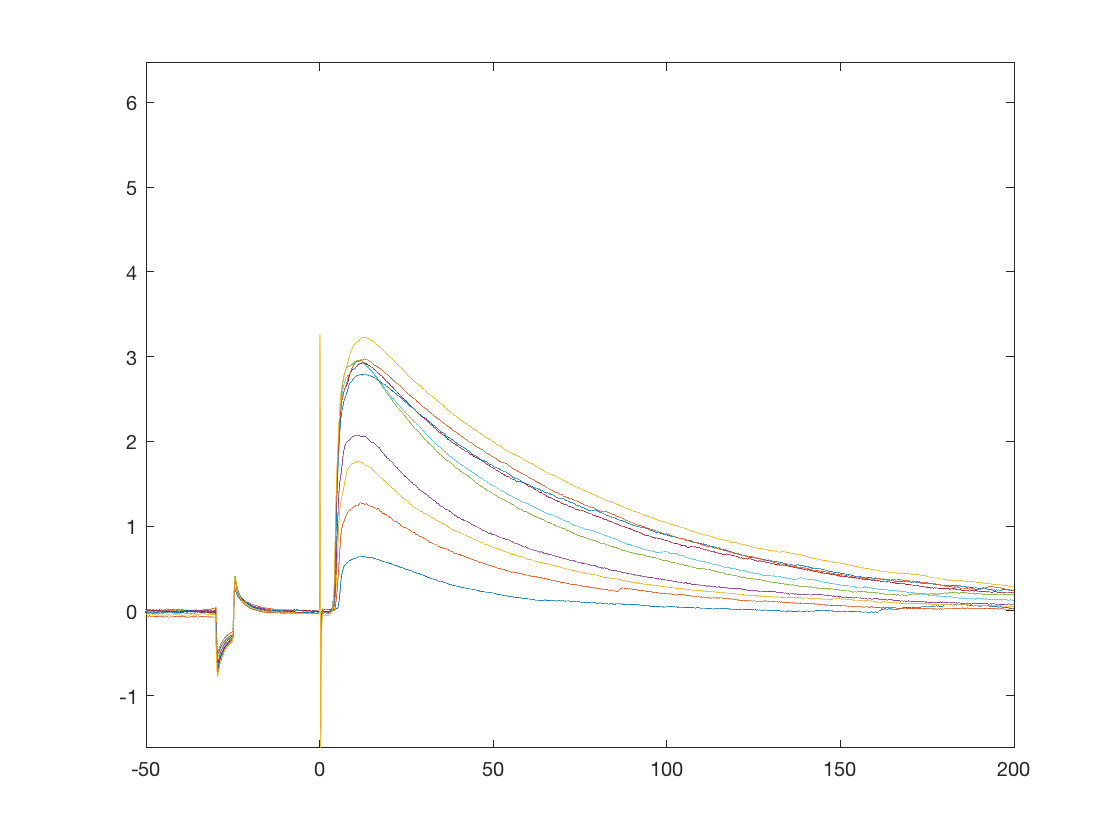


figure;
plot(t_zero,in);
ylim([-0.5*(max(in(10,10040:14000))) 2*(max(in(10,10040:14000)))])
xlim([-50 200])



range = [1 2 3 4 5 6 7 8 9 10];
%range = 8;

for k = range;
    
    Tau_nA(k) = in_peaks(k)*0.368;
    
    peaks(k) = find(in(k,:) == max(in(k,10040:14000)));
    
    Tau_range = find(in(k,10040:14000)>Tau_nA(k));
    
    Tau_max = max(Tau_range);
    
    Tau_t(k) = t_zero(Tau_max)+502;
    
end

%peaks'
Tau_nA = Tau_nA'

Tau_nA =     0.2362
    0.4697
    0.6493
    0.7632
    1.0906
    1.0751
    1.0770
    1.0276
    1.0941
    1.1894


Tau_t = Tau_t'

Tau_t =    46.1000
   54.7000
   57.0000
   58.7000
   63.4000
   70.1000
   82.6000
   89.3500
   87.2000
   89.7500





for q = range;
    peak_times(q) = t_zero(peaks(q));
end

peak_times'

ans =    12.0500
   11.8500
   10.8000
   10.3000
   11.6500
   11.7500
   12.4000
   12.7500
   12.9500
   12.5000



for z = range;
    Tau(z) = (Tau_t(z)-peak_times(z));
end

Tau = Tau'

Tau =    34.0500   42.8500   46.2000   48.4000   51.7500   58.3500   70.2000   76.6000   74.2500   77.2500


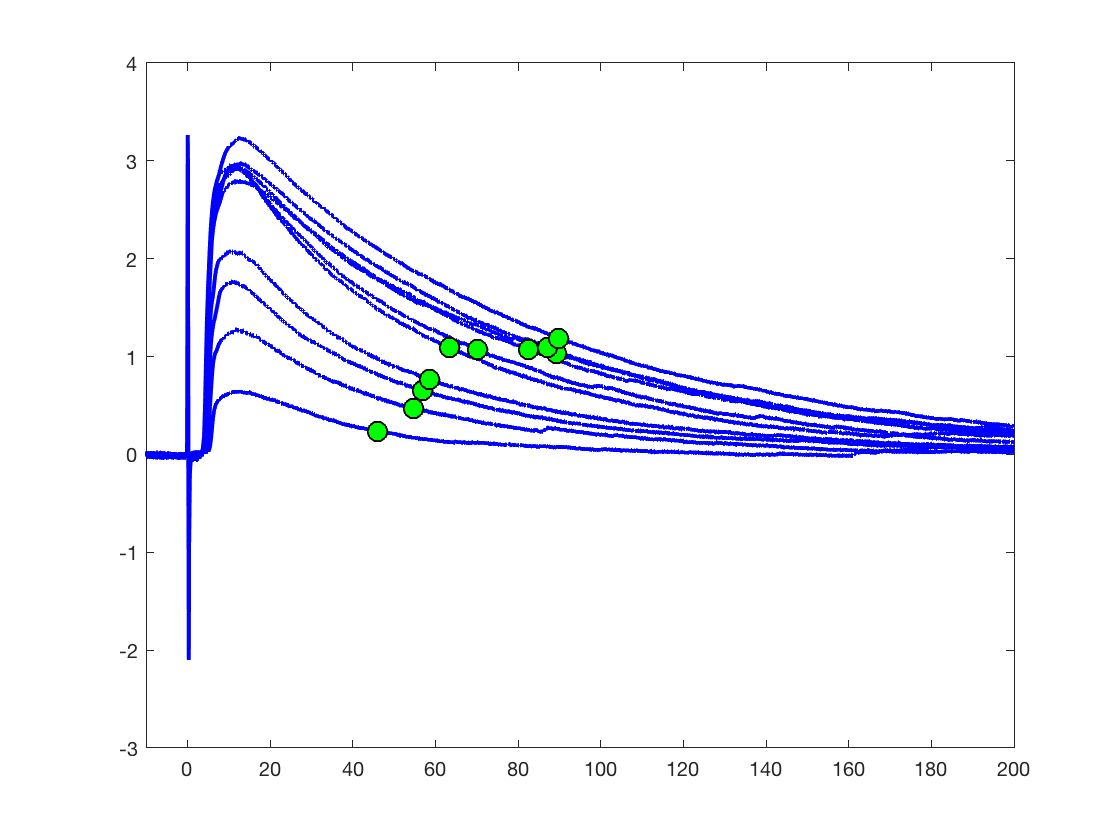



combined_tau(:,o) = Tau;
o = o + 1;

combined_tau_means(p) = mean(Tau(5:10));
p = p + 1;


figure;
plot(t_zero,in,'LineWidth',2,'color','b');
hold on
plot(Tau_t,Tau_nA,'o','MarkerEdgeColor','none','MarkerFaceColor','g','MarkerEdgeColor','k',"MarkerSize",10)
xlim([-10 200]);

%ylim([-0.1 0.8])







## Bin responses 


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%    

binned_Tau = NaN(10,200);

aa 

aa = 1

bb

bb = 1

cc

cc = 1

dd

dd = 1

ee

ee = 1

ff

ff = 1

gg

gg = 1

hh

hh = 1

jj

jj = 1

kk

kk = 1

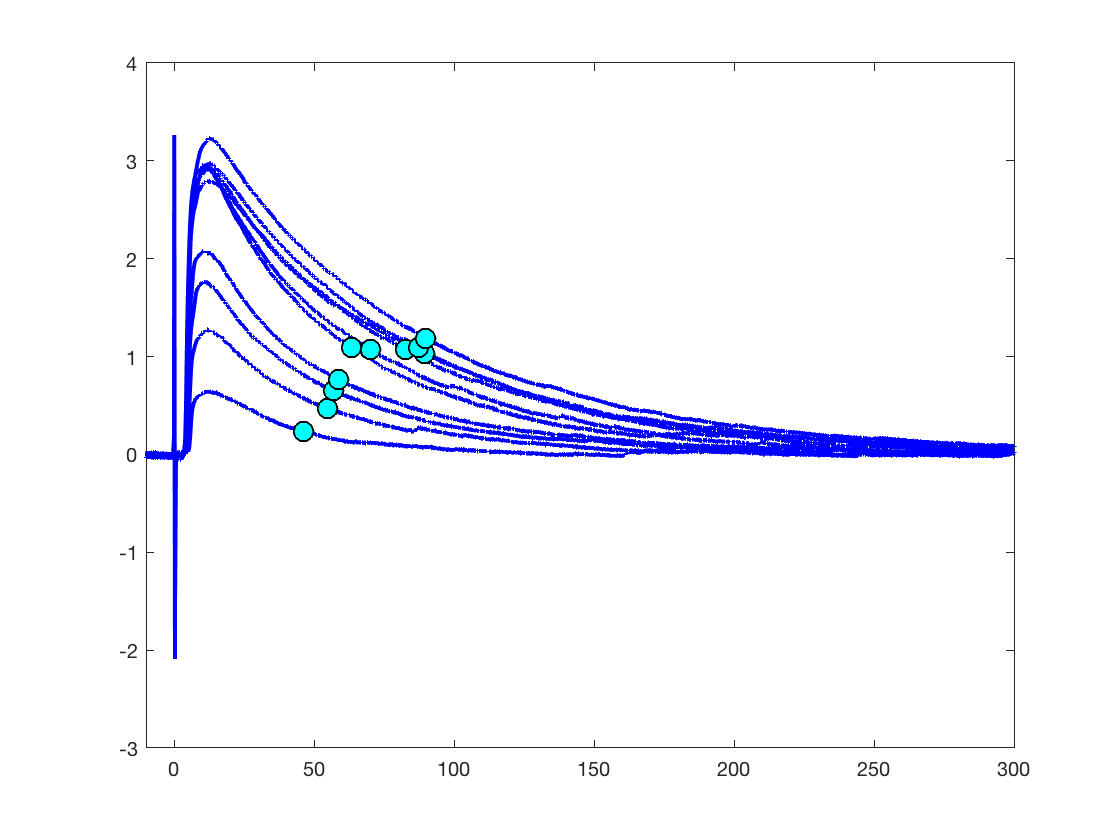

%




vv = 1;

for zz = 1:10;
                if max(in(zz,10040:20000)) < 0.75
                   binned_Tau(1,aa) = NaN;                   
                   binned_Tau(2,bb) = NaN;
                   binned_Tau(3,cc) = NaN;
                   binned_Tau(4,dd) = NaN;
                   binned_Tau(5,ee) = NaN;
                   binned_Tau(6,ff) = NaN;
                   binned_Tau(7,gg) = NaN;
                   binned_Tau(8,hh) = NaN;
                   binned_Tau(9,jj) = NaN;
                   binned_Tau(10,kk) = NaN; 
                   
                elseif  max(in(zz,10040:20000)) < 1.50
                   binned_Tau(1,aa) = Tau(zz);
                   aa = aa+1;
                   
                   binned_Tau(2,bb) = NaN;
                   binned_Tau(3,cc) = NaN;
                   binned_Tau(4,dd) = NaN;
                   binned_Tau(5,ee) = NaN;
                   binned_Tau(6,ff) = NaN;
                   binned_Tau(7,gg) = NaN;
                   binned_Tau(8,hh) = NaN;
                   binned_Tau(9,jj) = NaN;
                   binned_Tau(10,kk) = NaN;
                  
                   
                elseif max(in(zz,10040:20000)) < 3.00
                   binned_Tau(2,bb) = Tau(zz);              
                   bb = bb+1;
                   
                   binned_Tau(1,aa) = NaN;
                   binned_Tau(3,cc) = NaN;
                   binned_Tau(4,dd) = NaN;
                   binned_Tau(5,ee) = NaN;
                   binned_Tau(6,ff) = NaN;
                   binned_Tau(7,gg) = NaN;
                   binned_Tau(8,hh) = NaN;
                   binned_Tau(9,jj) = NaN;
                   binned_Tau(10,kk) = NaN;
                   
                   
                elseif max(in(zz,10040:20000)) < 3.50
                    
                   binned_Tau(3,cc) = Tau(zz);
                   cc = cc+1;
                   
                   binned_Tau(1,aa) = NaN;
                   binned_Tau(2,bb) = NaN;
                   binned_Tau(4,dd) = NaN;
                   binned_Tau(5,ee) = NaN;
                   binned_Tau(6,ff) = NaN;
                   binned_Tau(7,gg) = NaN;
                   binned_Tau(8,hh) = NaN;
                   binned_Tau(9,jj) = NaN;
                   binned_Tau(10,kk) = NaN;
                 
                   
                elseif max(in(zz,10040:20000)) <  2.25 
                   
                   binned_Tau(4,dd) = Tau(zz);
                   dd = dd+1;
                   
                   binned_Tau(1,aa) = NaN;
                   binned_Tau(2,bb) = NaN;
                   binned_Tau(3,cc) = NaN;
                   binned_Tau(5,ee) = NaN;
                   binned_Tau(6,ff) = NaN;
                   binned_Tau(7,gg) = NaN;
                   binned_Tau(8,hh) = NaN;
                   binned_Tau(9,jj) = NaN;
                   binned_Tau(10,kk) = NaN;
                   
                   
                elseif max(in(zz,10040:20000)) < 4.00 
                   binned_Tau(5,ee) = Tau(zz);
                   ee = ee+1;
                   
                   binned_Tau(1,aa) = NaN;
                   binned_Tau(2,bb) = NaN;
                   binned_Tau(3,cc) = NaN;
                   binned_Tau(4,dd) = NaN;
                   binned_Tau(6,ff) = NaN;
                   binned_Tau(7,gg) = NaN;
                   binned_Tau(8,hh) = NaN;
                   binned_Tau(9,jj) = NaN;
                   binned_Tau(10,kk) = NaN;
                         
                   
                elseif max(in(zz,10040:20000)) < 2.00 
                   binned_Tau(6,ff) = Tau(zz);
                   ff = ff+1;
                   
                   binned_Tau(1,aa) = NaN;
                   binned_Tau(2,bb) = NaN;
                   binned_Tau(3,cc) = NaN;
                   binned_Tau(4,dd) = NaN;
                   binned_Tau(5,ee) = NaN;
                   binned_Tau(7,gg) = NaN;
                   binned_Tau(8,hh) = NaN;
                   binned_Tau(9,jj) = NaN;
                   binned_Tau(10,kk) = NaN;
                  
                   % collect rep trace

                   %rep_traces(aaa,:) = in(zz,:);
                   %aaa = aaa+1;
                   
                elseif max(in(zz,10040:20000)) < 2.00 
                   binned_Tau(7,gg) = Tau(zz);
                   gg = gg+1;
                   
                   binned_Tau(1,aa) = NaN;
                   binned_Tau(2,bb) = NaN;
                   binned_Tau(3,cc) = NaN;
                   binned_Tau(4,dd) = NaN;
                   binned_Tau(5,ee) = NaN;
                   binned_Tau(6,ff) = NaN;
                   binned_Tau(8,hh) = NaN;
                   binned_Tau(9,jj) = NaN;
                   binned_Tau(10,kk) = NaN;
                   
                   % collect rep trace

                   %rep_traces(aaa,:) = in(zz,:);
                   %aaa = aaa+1;
                   
                elseif max(in(zz,10040:20000)) < 2.00 
                   binned_Tau(8,hh) = Tau(zz);
                   hh = hh+1;
                   
                   binned_Tau(1,aa) = NaN;
                   binned_Tau(2,bb) = NaN;
                   binned_Tau(3,cc) = NaN;
                   binned_Tau(4,dd) = NaN;
                   binned_Tau(5,ee) = NaN;
                   binned_Tau(6,ff) = NaN;
                   binned_Tau(7,gg) = NaN;
                   binned_Tau(9,jj) = NaN;
                   binned_Tau(10,kk) = NaN;
                   
                   % collect rep trace

                   %rep_traces(aaa,:) = in(zz,:);
                   %aaa = aaa+1;
               
                elseif max(in(zz,10040:20000)) < 2.00 
                   binned_Tau(9,jj) = Tau(zz);
                   jj = jj+1;
                   
                   binned_Tau(1,aa) = NaN;
                   binned_Tau(2,bb) = NaN;
                   binned_Tau(3,cc) = NaN;
                   binned_Tau(4,dd) = NaN;
                   binned_Tau(5,ee) = NaN;
                   binned_Tau(6,ff) = NaN;
                   binned_Tau(7,gg) = NaN;
                   binned_Tau(8,hh) = NaN;
                   binned_Tau(10,kk) = NaN;
                   
                   
                elseif max(in(zz,10040:20000)) < 2.00 
                   binned_Tau(10,kk) = Tau(zz);
                   kk = kk+1;
                   
                   binned_Tau(1,aa) = NaN;
                   binned_Tau(2,bb) = NaN;
                   binned_Tau(3,cc) = NaN;
                   binned_Tau(4,dd) = NaN;
                   binned_Tau(5,ee) = NaN;
                   binned_Tau(6,ff) = NaN;
                   binned_Tau(7,gg) = NaN;
                   binned_Tau(8,hh) = NaN;
                   binned_Tau(9,jj) = NaN;
                   
                end
            end

            clear vv
            

            
%}




figure;
plot(t_zero,in,'LineWidth',2,'color','b');
hold on
plot(Tau_t,Tau_nA,'o','MarkerEdgeColor','none','MarkerFaceColor','c','MarkerEdgeColor','k',"MarkerSize",10)
xlim([-10 300]);

%ylim([-0.1 3.0])

in_peaks'

ans =     0.6419
    1.2763
    1.7644
    2.0739
    2.9636
    2.9214
    2.9265
    2.7925
    2.9730
    3.2321


Tau'

ans =    34.0500
   42.8500
   46.2000
   48.4000
   51.7500
   58.3500
   70.2000
   76.6000
   74.2500
   77.2500


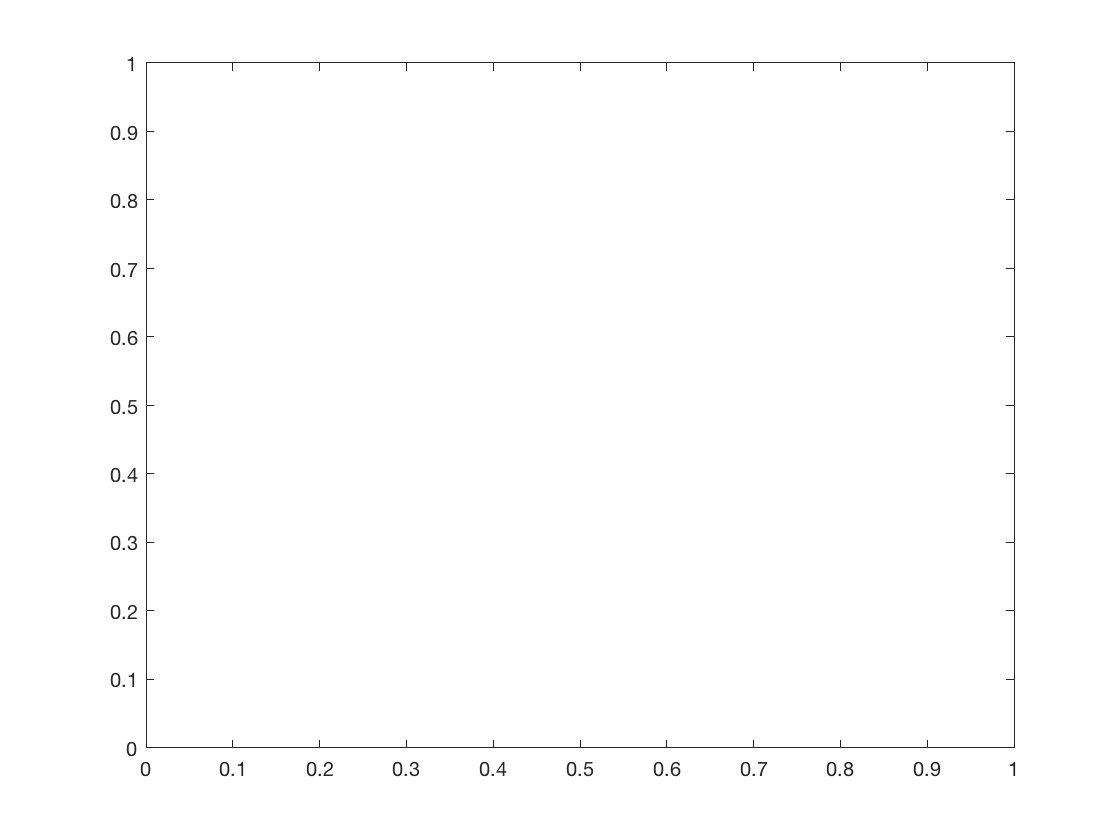




rep_traces_mean = nanmean(rep_traces);


figure;
plot(t_zero,rep_traces,'linewidth',2,'color',[0.8 0.8 0.8]);
hold on
plot(t_zero,rep_traces_mean,'linewidth',3,'color','r')

%xlim([-10 150]);

Tau = Tau'

Tau =    34.0500
   42.8500
   46.2000
   48.4000
   51.7500
   58.3500
   70.2000
   76.6000
   74.2500
   77.2500



clear Tau_max Tau_nA Tau_range Tau_t


## collect into the cell-averaged combined variable



binned_Tau_cell = nanmean(binned_Tau,2);

%combined_binned_Tau(:,x) = binned_Tau_cell;
%x = x+1;
%clear binned_Tau binned_Tau_cell


if isnan(binned_Tau_cell(1)) == 1
    combined_binned_Tau(1,aaa) = NaN;
else
    combined_binned_Tau(1,aaa) = binned_Tau_cell(1);
    aaa = aaa +1;
end


if isnan(binned_Tau_cell(2)) == 1
    combined_binned_Tau(2,bbb) = NaN;
else
    combined_binned_Tau(2,bbb) = binned_Tau_cell(2);
    bbb = bbb +1;
end


if isnan(binned_Tau_cell(3)) == 1
    combined_binned_Tau(3,ccc) = NaN;
else
    combined_binned_Tau(3,ccc) = binned_Tau_cell(3);
    ccc = ccc +1;
end


if isnan(binned_Tau_cell(4)) == 1
    combined_binned_Tau(4,ddd) = NaN;
else
    combined_binned_Tau(4,ddd) = binned_Tau_cell(4);
    ddd = ddd +1;
end

if isnan(binned_Tau_cell(5)) == 1
    combined_binned_Tau(5,eee) = NaN;
else
    combined_binned_Tau(5,eee) = binned_Tau_cell(5);
    eee = eee +1;
end


if isnan(binned_Tau_cell(6)) == 1
    combined_binned_Tau(6,fff) = NaN;
else
    combined_binned_Tau(6,fff) = binned_Tau_cell(6);
    fff = fff +1;
end

if isnan(binned_Tau_cell(7)) == 1
    combined_binned_Tau(7,ggg) = NaN;
else
    combined_binned_Tau(7,ggg) = binned_Tau_cell(7);
    ggg = ggg +1;
end


if isnan(binned_Tau_cell(8)) == 1
    combined_binned_Tau(8,hhh) = NaN;
else
    combined_binned_Tau(8,hhh) = binned_Tau_cell(8);
    hhh = hhh +1;
end

if isnan(binned_Tau_cell(9)) == 1
    combined_binned_Tau(9,jjj) = NaN;
else
    combined_binned_Tau(9,jjj) = binned_Tau_cell(9);
    jjj = jjj +1;
end


if isnan(binned_Tau_cell(10)) == 1
    combined_binned_Tau(10,kkk) = NaN;
else
    combined_binned_Tau(10,kkk) = binned_Tau_cell(10);
    kkk = kkk +1;
end


clear binned_Tau 




